%1
clear
clf
load spectra.mat
who


Your variables are:

CIED50       
CIED65       
R1           
R2           
Tungsten60W  
XYZ          
ans          
chips20      
f11          
plank90K     
wavelength   
xyz          




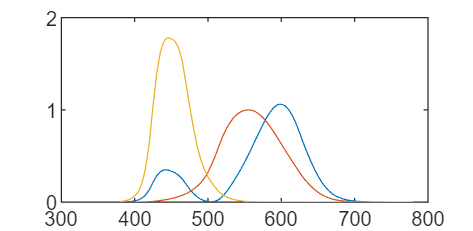

plot(wavelength, xyz)

%1.1
reflectAll = ones(length(CIED65), 1);
[X, Y, Z] = spectra2xyz(reflectAll, CIED65)

X = 95.0437

Y = 100

Z = 108.8818

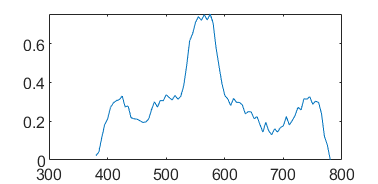

%1.2
plot(wavelength, R1)

[X1, Y1, Z1] = spectra2xyz(R1, CIED65)

X1 = 40.0489

Y1 = 49.7395

Z1 = 26.6104

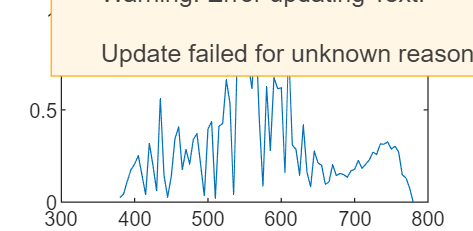

plot(wavelength, R2)

[X2, Y2, Z2] = spectra2xyz(R2, CIED65)

X2 = 40.0489

Y2 = 49.7395

Z2 = 26.6104

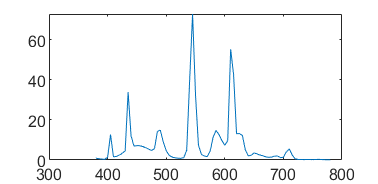

%1.3
plot(wavelength, f11)

[X3, Y3, Z3] = spectra2xyz(R1, f11)

X3 = 41.6587

Y3 = 53.3569

Z3 = 16.3345

[X4, Y4, Z4] = spectra2xyz(R2, f11)

X4 = 53.9818

Y4 = 63.4675

Z4 = 20.7173

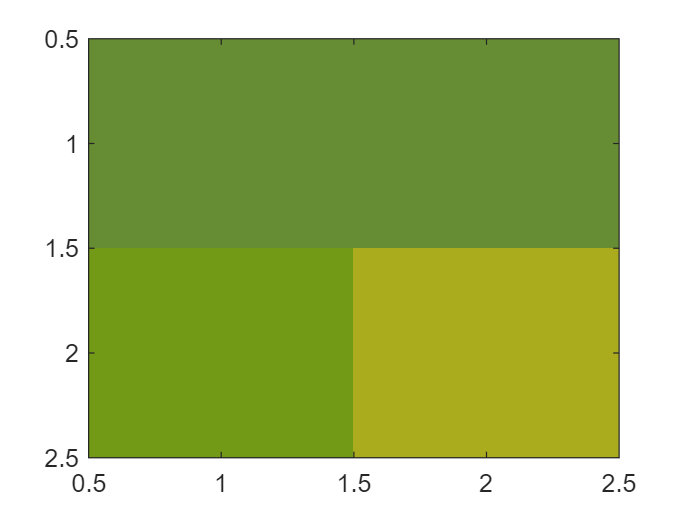

%1.5
[r1, g1, b1] = myxyz2rgb(X1, Y1, Z1);
[r2, g2, b2] = myxyz2rgb(X2, Y2, Z2);
[r3, g3, b3] = myxyz2rgb(X3, Y3, Z3);
[r4, g4, b4] = myxyz2rgb(X4, Y4, Z4);
map=[r1 g1 b1; r2 g2 b2; r3 g3 b3; r4 g4 b4];
map=min(1,max(0,map));
image([1 2; 3 4])
colormap(map)
imwrite(colormap(map), "yourfilename", "png")

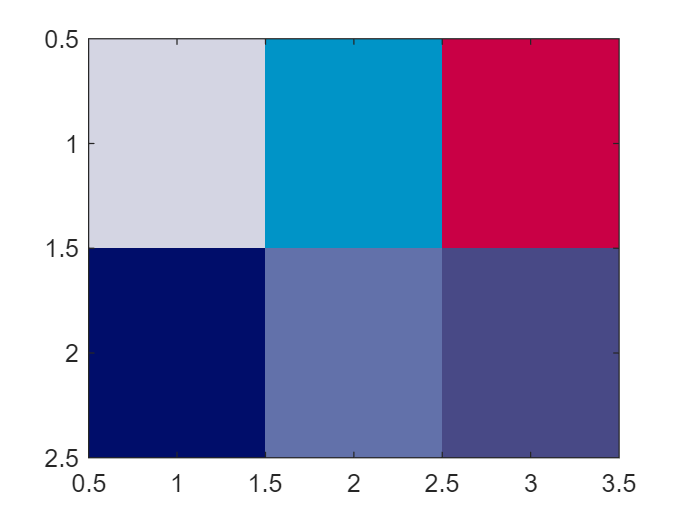

%2.2
[r1, g1, b1] = myxyz2rgb(80.43, 84, 96.5);
[r2, g2, b2] = myxyz2rgb(25.84, 42.52, 80.88);
[r3, g3, b3] = myxyz2rgb(37.36, 18.44, 27.52);
[r4, g4, b4] = myxyz2rgb(7.40, 5.74, 40.36);
[r5, g5, b5] = myxyz2rgb(43.915, 44.87, 69.43);
[r6, g6, b6] = myxyz2rgb(31.6, 30.48, 54.2);
map=[r1 g1 b1; r2 g2 b2; r3 g3 b3; r4 g4 b4; r5 g5 b5; r6 g6 b6];
map=min(1,max(0,map));
image([1 2 3; 4 5 6])
colormap(map)
imwrite(colormap(map), "yourfilename", "png")

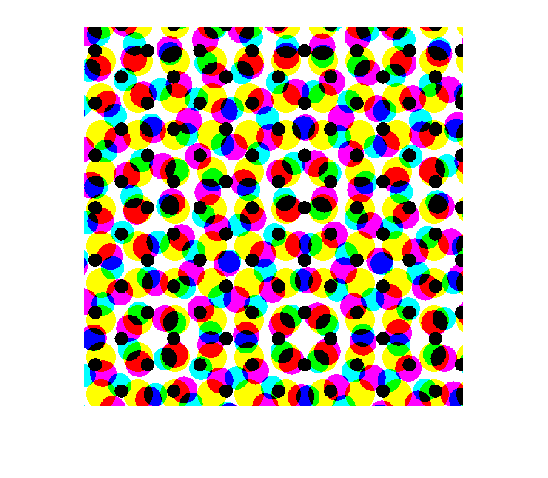

%3.1
[C, M, Y, K]=tiffread("halftone.tif");
[R, G, B]=cmyk2rgb(C, M, Y, K);
imshowrgb(R, G, B)

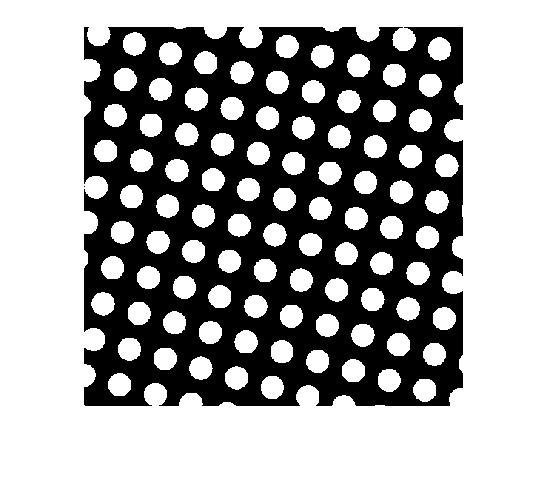

imshow(C)

sum(sum(C & M & ~Y & ~K))/512^2

ans = 0.0618

C1 = C(129:384, 129:384);
M1 = M(129:384, 129:384);
Y1 = Y(129:384, 129:384);
K1 = K(129:384, 129:384);

Demichel_test(C1, M1, Y1, K1)

ans =     0.1628
    0.0765
    0.1351
    0.2090
    0.0191
    0.0648
    0.0858
    0.0096
    0.1126
    0.0185



C2 = C(139:394, 139:394);
M2 = M(129:384, 129:384);
Y2 = Y(139:394, 139:394);
K2 = K(129:384, 129:384);

Demichel_test(C2, M2, Y2, K2)

ans =     0.1868
    0.0833
    0.1170
    0.1757
    0.0221
    0.0566
    0.0881
    0.0103
    0.1399
    0.0107


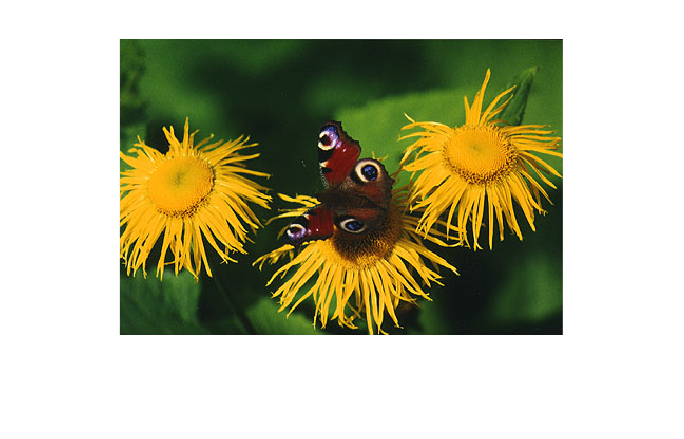

%4
[R, G, B] = tiffread("Butterfly.tif");
imshowrgb(R ,G, B)

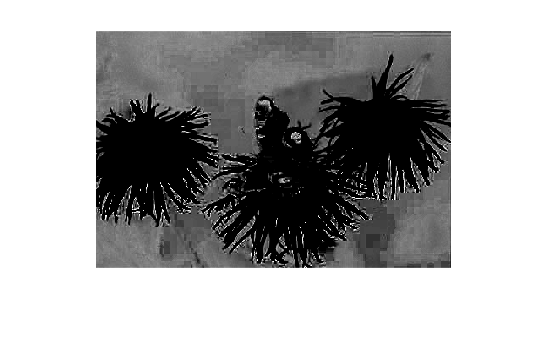

%4.1
[C, M, Y, K]=rgb2cmyk(R,G,B);
figure(1)
imshow(C)

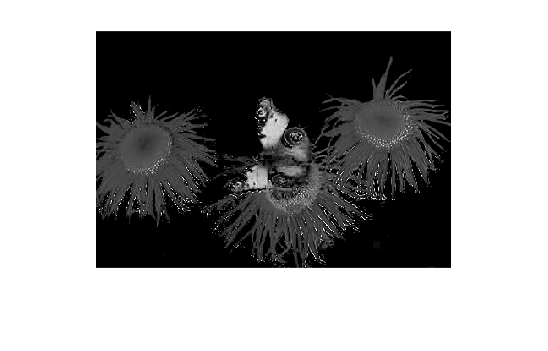

figure(2)
imshow(M)

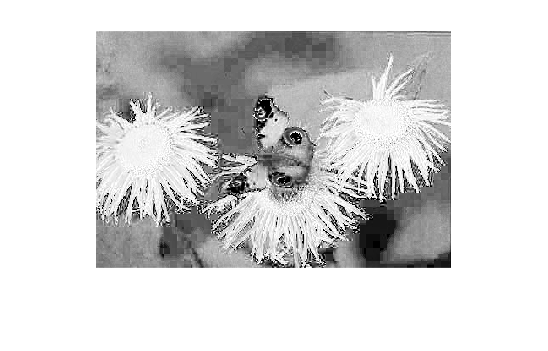

figure(3)
imshow(Y)

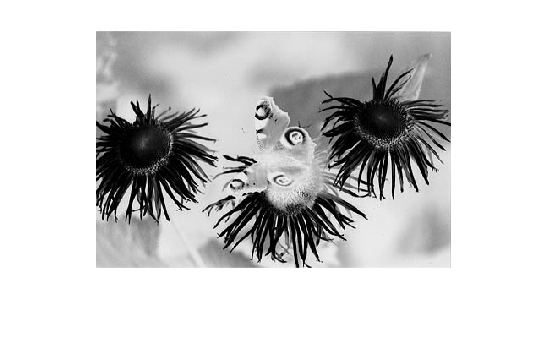

figure(4)
imshow(K)

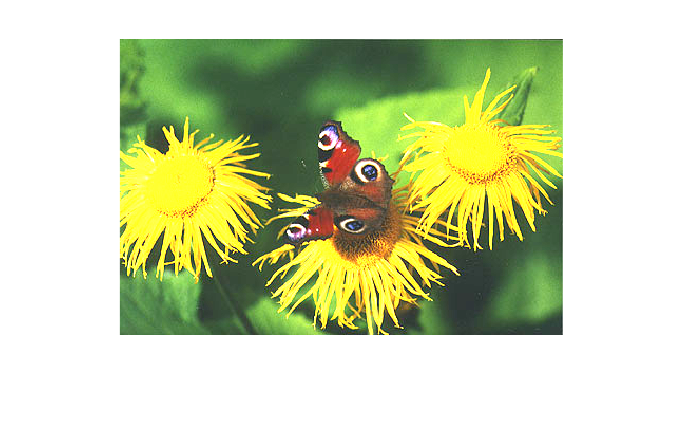

%4.2
[L, a, b]=myrgb2lab(R,G,B);
[R2, G2, B2]=mylab2rgb(L+20, a, b);
imshowrgb(R2, G2, B2)

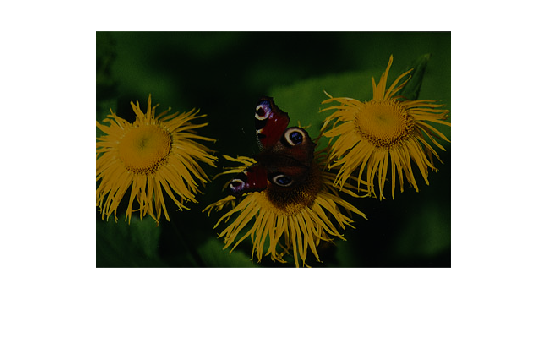

figure
[R3, G3, B3]=mylab2rgb(L-20, a, b);
imshowrgb(R3, G3, B3)

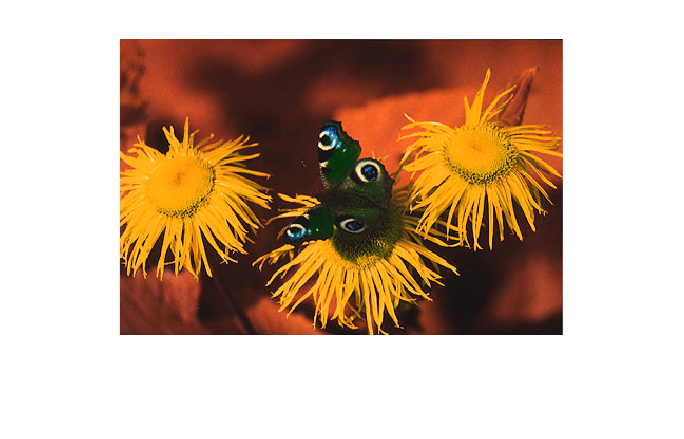

%4.3
[R2, G2, B2]=mylab2rgb(L, -a, b);
imshowrgb(R2, G2, B2)

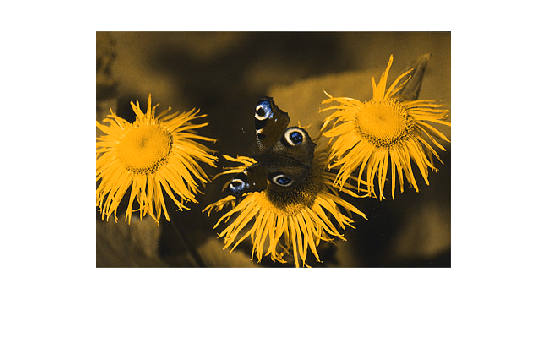

[R2, G2, B2]=mylab2rgb(L, 0, b);
imshowrgb(R2, G2, B2)

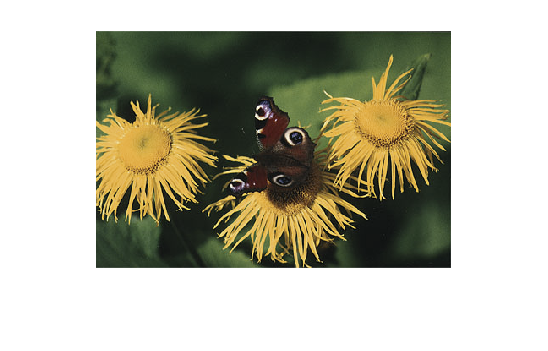

%4.4
[R2, G2, B2]=mylab2rgb(L, 0.5*a, 0.5*b);
imshowrgb(R2, G2, B2)

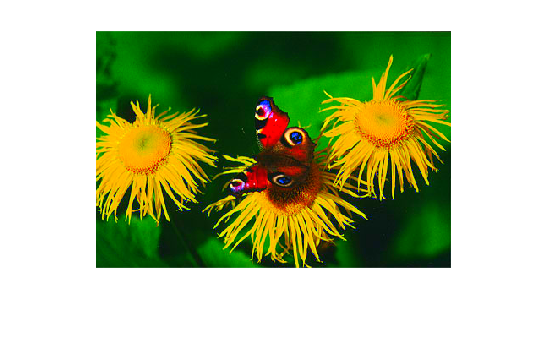

[R2, G2, B2]=mylab2rgb(L, 3*a, 3*b);
imshowrgb(R2, G2, B2)

%5.1
[X1, Y1, Z1] = spectra2xyz(1, CIED65)

X1 = 95.0437

Y1 = 100

Z1 = 108.8818

[r,g,b] = myxyz2rgb(X1,Y1,Z1);

[X2, Y2, Z2] = spectra2xyz(1, Tungsten60W)

X2 = 112.9853

Y2 = 100.0000

Z2 = 28.5810

[r2,g2,b2] = myxyz2rgb(X2,Y2,Z2);

[X3, Y3, Z3] = spectra2xyz(1, plank90K)

X3 = 97.0578

Y3 = 100

Z3 = 141.1759

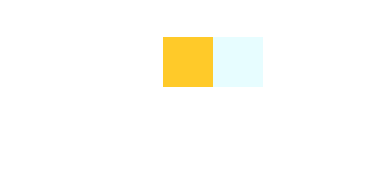

[r3,g3,b3] = myxyz2rgb(X3,Y3,Z3);

showRGB([r g b; r2 g2 b2; r3 g3 b3])

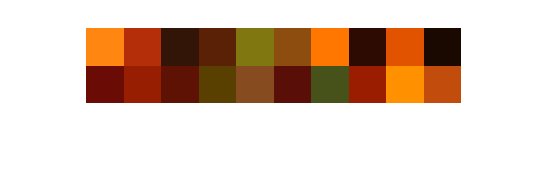

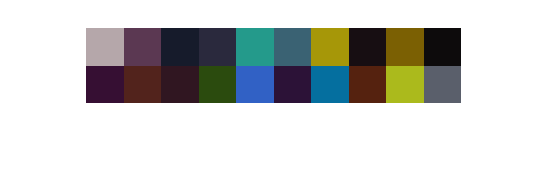

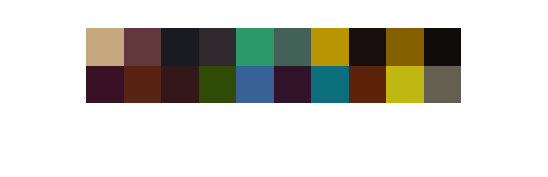

%5.2
showRGB_20

ans =    42.6575   37.7851    9.2111


ans =    35.5059   37.1884   45.1131


ans =    35.1115   37.2965   34.8667


ans =    67.8620   67.4182   67.4989


ans =     0.1015   -1.7637   -1.0122


ans =     7.4954    6.9190    7.0603


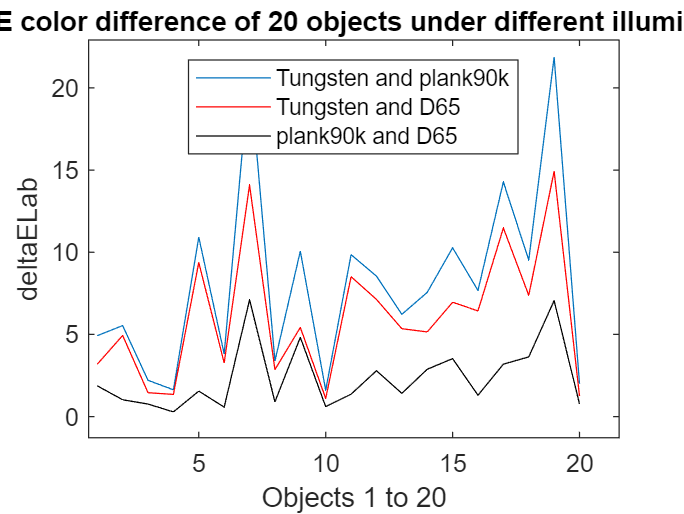

%5.3
plot_deltaE

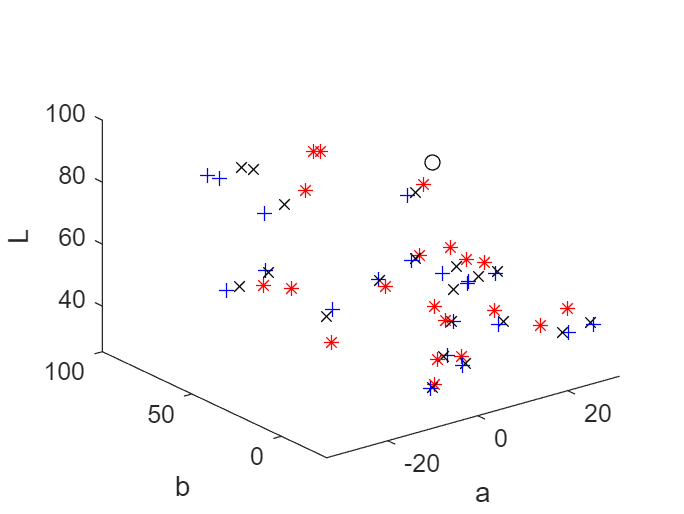

%5.5
plot_Lab